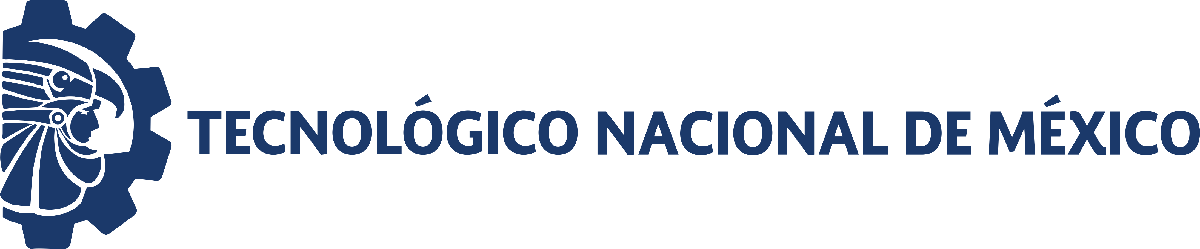                                 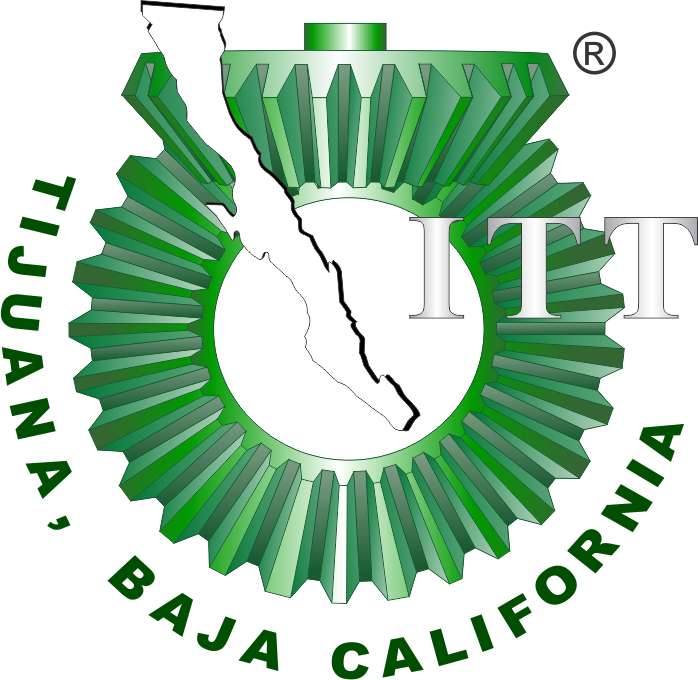

# Práctica 2: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

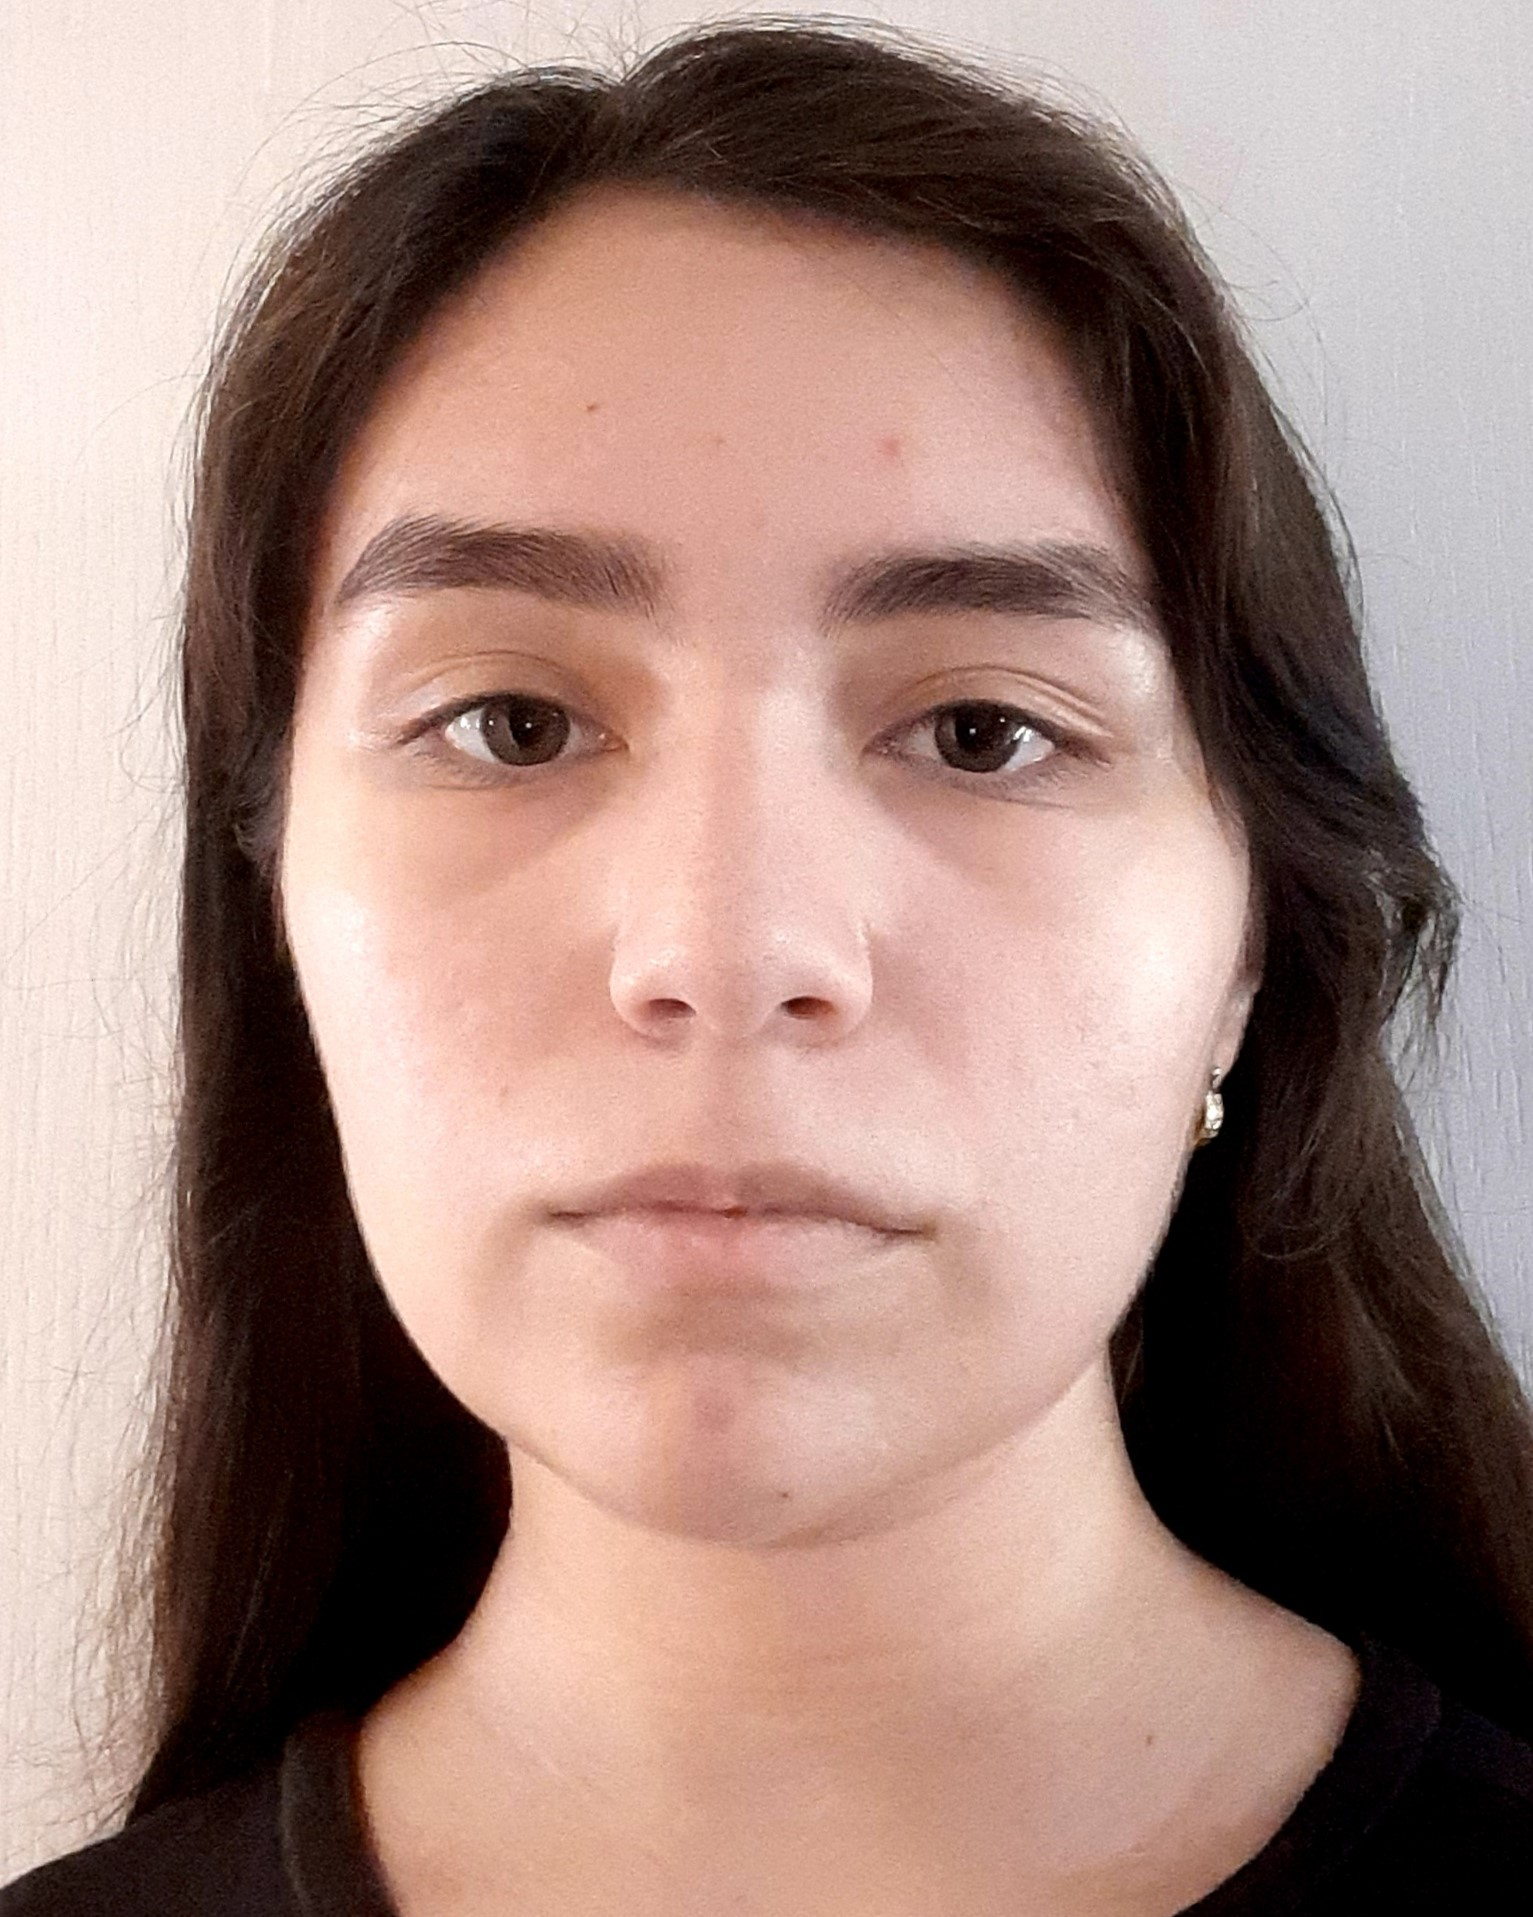

Nombre del alumno: Villa Camacho Abigail

Número de control: 22212276

Correo institucional: L22212276**@tectijuana.edu..mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema_circuito2';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('sistema_circuito2/Ppa(t)', 'Minimum','-0.2');
set_param('sistema_circuito2/Ppa(t)', 'Maximum','1');
set_param('sistema_circuito2/Ppa(t)', 'Seed','106');
set_param('sistema_circuito2/Ppa(t)', 'SampleTime','0.5');

## Respuesta en lazo abierto

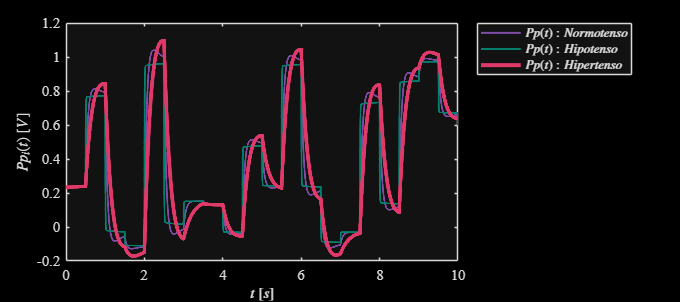

Signal = 'LazoAbierto';
x0 = sim(file,parameters);
%writematrix(x0.Ppa,'signal.xlsx');
plotsignals0(x0.t,x0.Pp0,x0.Pp1,x0.Pp2,Signal)

## Respuesta en lazo abierto y lazo cerrado (PID)

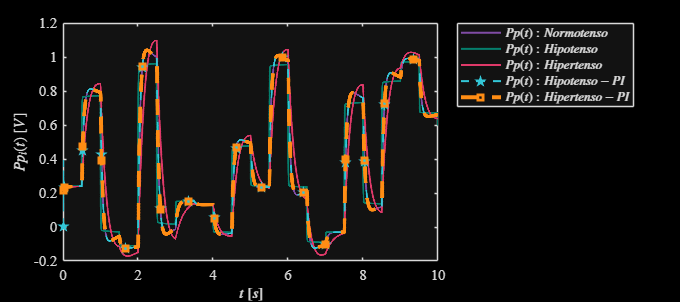

Signal = 'laPID'; %Step
x1 = sim(file,parameters);
plotsignals1(x1.t,x1.Pp0,x1.Pp1,x1.Pp2,x1.Pp3,x1.Pp4,Signal)

## Función: Respuesta a las señales

function plotsignals0(t,Pp0,Pp1,Pp2,Signal)
set(figure(),'Color','k')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [0.4980,0.2980,0.6471;
            0.0196,0.4980,0.4275;
            0.8745,0.2235,0.4118;
           ];
colororder(mycolors)

p = plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-','LineWidth', 1.5, 'MarkerSize', 3, 'MarkerIndices', 1:1000:length(t));
set(p(3), 'LineWidth', 3);
L = legend('$Pp(t): Normotenso$', '$Pp(t): Hipotenso$','$Pp(t): Hipertenso$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11 )

    %exportgraphics(gcf,[Signal, '.pdf'],'ContentType','vector')
    %exportgraphics(gcf,[Signal, '.png'],'ContentType','vector')

end

function plotsignals1(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
set(figure(),'Color','k')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [0.4980,0.2980,0.6471;
            0.0196,0.4980,0.4275;
            0.8745,0.2235,0.4118;
            0.2000,0.7804,0.8471; 
            1.0000,0.5529,0.0784;
            ];
colororder(mycolors)

p = plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-',t, Pp3, '--pentagram',t, Pp4, '--square','LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
set(p(5), 'LineWidth', 3);
L = legend('$Pp(t): Normotenso$', '$Pp(t): Hipotenso$','$Pp(t): Hipertenso$','$Pp(t): Hipotenso - PI$','$Pp(t): Hipertenso - PI$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');

xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11 )

    %exportgraphics(gcf,[Signal, '.pdf'],'ContentType','vector')
    %exportgraphics(gcf,[Signal, '.png'],'ContentType','vector')

end